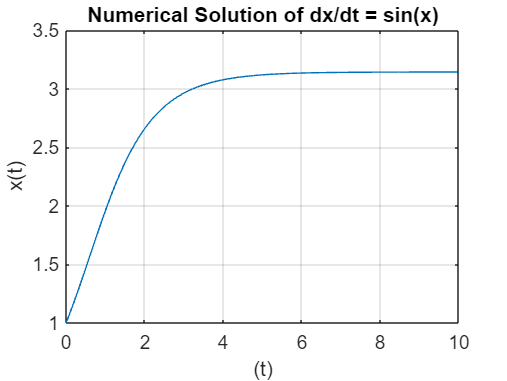

% Define the differential equation function dx/dt = sin(x)
dxdt = @(x) sin(x);

% Initial value of x and time step
x0 = 1;         % Initial value of x
t0 = 0;         % Initial time
tfinal = 10;    % Final time
delta_t = 0.01; % Time step

% Initialize arrays to store time sand solution values
t_values = t0:delta_t:tfinal;
x_values = zeros(size(t_values));
x_values(1) = x0; % Set initial value

% Numerical integration using Euler's method
for i = 2:length(t_values)
    x_values(i) = x_values(i-1) + delta_t * dxdt(x_values(i-1));
end

% Plot the solution x(t)
figure;
plot(t_values, x_values);
xlabel('(t)');
ylabel('x(t)');
title('Numerical Solution of dx/dt = sin(x)');
grid on;